**Daniel Park | 11/17/20**

# **Using Eigenfaces to Identify Masked Individuals **

## **1. Summary**

Face recognition is a method of identifying or verifying the identity of an individual using their face. Face recognition systems can be used to identify people in photos, video, or in real-time. Law enforcement may also use mobile devices to identify people during police stops. However, it has become a problem since people with masks are often hard to detect on facial recognition systems This report will detail the process of implementing a face recognition system that will randomly load a masked image and the algorithm will then find an image of the same person for their unmasked version using eigenfaces. In addition to a working system, this report would also address how the introduction of a face mask obstructing some vital facial parts will affect the system in place and how we would fix our system in accordance to that. The introduction will talk about the implications of the project and the potential bias of the algorithm. The methods will go into detail about the process of the created algorithm with eigenfaces. The detailed findings will discuss the completed system and the corresponding graphs for verification and validation information, the recommendation section goes over crucial findings of the model and areas for future investigation, and finally the references section with all the sources reference in this report paper.

## **2. Introduction**

Facial Recognition Systems is a relatively modern technology that is capable of matching a human face from a digital image or video frame against a database of faces. The technology authenticates users through identification services while also being deployed in advanced human-computer interaction, video surveillance, and more recently, smartphone and robotics identification software. 

Over the past couple of decades, people have discovered numerous ways of deploying a facial recognition software such using different types of machine learning techniques or using a convolutional neural network (CNN for short) to recognize faces. However, the way this report will explore a more straightforward approach founded by Matthew A. Turk and Alex P. Pentland in 1991 is called the "eigenvector-based recognition system" and have the software automatically or manually load a specific image within the dataset and find an image of the same person from the same dataset. [1]

Although deploying a facial match recognition system is straightforward enough, possible ethical issues or obstructions may surface primarily during this time of the mass pandemic. During COVID-19, the wearing of facemasks has become an essential part of public life, as has the enforcement of mask-wearing in stores and other public places. This type of system that identifies faces may be difficult with the introduction of a mask on the face. Since a mask covers a large part of the face, the system would be more inaccurate or not even being able to match face images. Furthermore, since this algorithm would be servicing a large and diverse population, not just a specific demographic, reducing bias in training data will be necessary to prevent accuracy issues once deployed.

So in light of these possible controversies, this report will answer the question ***"Can we make an algorithm that takes in a dataset of people and using eigenfaces, detects an image from within the dataset that matches the face?"*** ***"Is it possible to take into account the facemasks people wear now that will now obstruct a large majority of the face when matching faces? Moreover, if so, how can we do it?"***

## **3. Methods**

*Having introduced the reader to terminology and ideas, this section should lay out the approaches you are using, both in terms of the chosen algorithm and the analysis you are doing with it. Use equations and dene all variables. (Go into detail later)*

### 3.1 Preparing the Dataset

In order to answer our question, we have to find a dataset that has a large number of individuals with a variety of images attached to each individual with a corresponding masked and unmasked image for each image. 

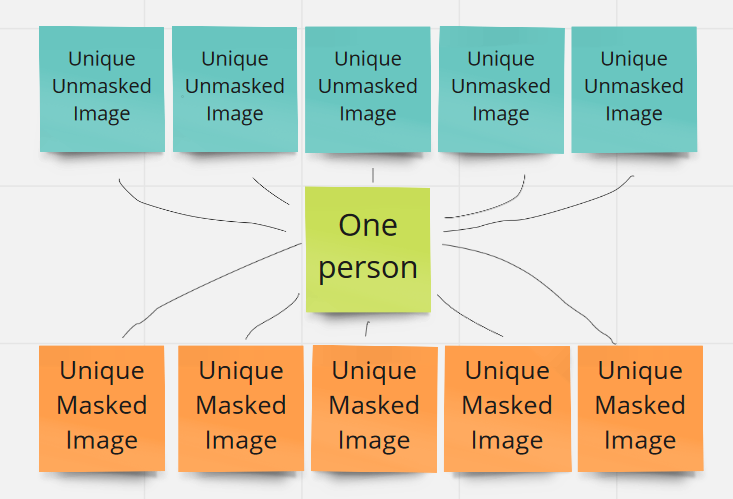

**Figure 1: A visual representation of the dataset necessary to solve that my question for this report. We need a dataset with the same number of unique unmasked images with their unique masked images counterparts. **

Unforunately, there are no datasets out there that will help us directly accomplish that, so we must take an existing database of faces and make a copy of each of those images with a mask on their face. The database that we will use is the the ORL (Our Database of Faces) Batabase from AT&T Laboratories in Cambridge. [2]

The ORL Database contains a set of face images taken between April 1992 and April 1994 at the laboratory for the sole purpose of a face recognition project carried out with the Speech, Vision, and Robot Group of the Cambridge University Engineering Department. The dataset has ten different images of each of 40 distinct subjects. For some subjects, the images were taken at different times, varying the lighting, facial  expressions (open / closed eyes, smiling / not smiling) and facial details (glasses / no glasses). All the images were taken against a dark homogeneous background with the subjects in an upright, frontal position (with tolerance for some side movement). [3]

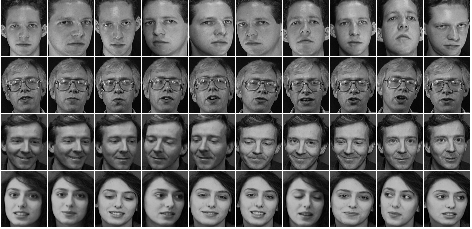

**Figure 2: A snapshot of four unique faces with ten different images for each face that are within the ORL Database**

This was a perfect dataset for use because the images were already in grayscale and each had the same resolution and dimension of a 92 x 112 pixel image. So using Adobe Photoshop, I saved the dataset to my computer and pasted in a grayscaled mask covering the nose and mouth of each face. Since the algorithm won't be affected by less subjects since we are not removing the ten images for each face, it will save time working with only ten subjects rather than pasting masks on Adobe Photoshop for longer than was necessary. The only requirements for the edited mask photos is that the mask should cover the nose and mouth that will help contain the spread of COVID-19.

So now I have two datasets with one called "no_mask_set" with ten unique people without masks and another one called "mask_set" with ten of the same people with masks. 

**Mask:                                                 No Mask:**

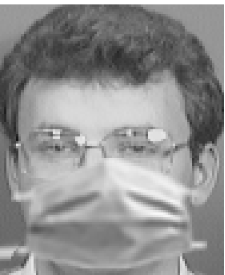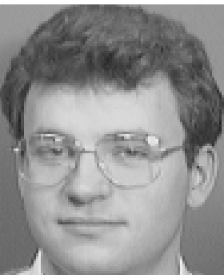

**Figure 3: A quick snapshot of what a image of the same person with a mask and one image of the person without a mask**

### 3.2 Image Loading

Now that we prepared both the mask dataset and the no mask dataset, we have to load them and prepare them for analysis. We need to load a random image and put it in a variable and another matrix that holds the images of the unmasked images and compare those with the random image loaded.

So first, we have to create a script that will load both prepared datasets that returns a numeric array form of the image for processing. The script will return a stored variable called "outputValue" that will have all the loaded images of the dataset onto it. In order to load the images into the array, we have to reshape the images to convert the images into a singular column matrix and added that singular column matrix to a larger matrix will hold all the singular column matrices for all the images within the dataset. 

To capture it formally, we want to obtain a set of images *I *where the *p *values represent the pixel darkness from 0 to 255.

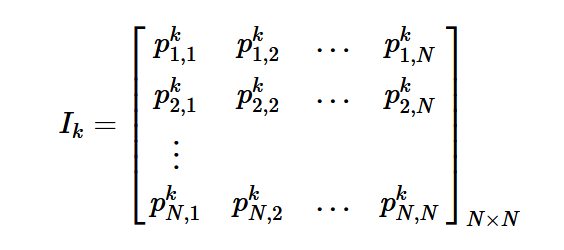

%%% NonMask Portion
%% Description
% Loads the no mask dataset in preparation for face recognition

%% Variables
loadedImage = [];
numImage = [];

%% Dataset Loading Function
if(isempty(loadedImage)) 
    allImages = zeros(112*92,... % Pixels of each image
        10); % Number of folders representing a single person
    cd(strcat('no_mask_set')); 
    for i=1:10 
        cd(strcat('s',num2str(i))); 
        for j=1:10 
            imageContainer = imread(strcat(num2str(j),'.pgm')); 
            allImages(:,(i-1)*10+j)... % get all images from each folder
                = reshape(imageContainer,size(imageContainer,1)... 
                *size(imageContainer,2),1); % reshape images into arrays for analysis
        end
        cd .. % changes folder directory back to load other faces
    end
    cd ..
    numImage = uint8(allImages); % changes all the images within the database to 8-bit images
end
loadedImage = ""; % Needs to return to empty next time image needs to be loaded
outputImage = numImage; 

%%% Mask Portion
%% Description
% Loads the mask dataset in preparation for face recognition

%% Variables
loadedImage1 = [];
numImage1 = [];

%% Dataset Loading Function
if(isempty(loadedImage1)) 
    allImages1 = zeros(112*92,... % Pixels of each image 
        10); % Number of folders representing a single person
    cd(strcat('mask_set')); 
    for i=1:10 
        cd(strcat('s',num2str(i))); 
        for j=1:10 
            imageContainer1 = imread(strcat(num2str(j),'.pgm')); 
            allImages1(:,(i-1)*10+j)... % get all images from each folder
                = reshape(imageContainer1,size(imageContainer1,1)... 
                *size(imageContainer1,2),1); % reshape images into arrays for analysis
        end
        cd .. % changes folder directory back to load other faces
    end
    cd ..
    numImage1 = uint8(allImages1); % changes all the images within the database to 8-bit images
end
loadedImage1 = ""; % Needs to return to empty next time image needs to be loaded
outputImage1 = numImage1; 

And now we obtained the set of images and placed them into a matrix, we can change the representation of a face image and concatenate all the rows into one big vector that formall would look like this where 

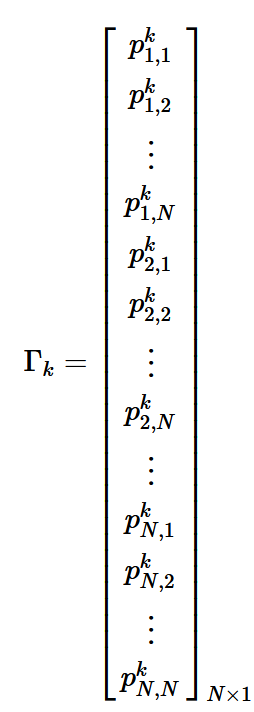

### 3.3 Computing the Eigenfaces

In order to start analysis on the images, we have to start by choosing an image I want to use for eigenvector face comparison. I load a random masked image from the masks database to be recognized later with a unmasked image into a single variable.

After that, we can start getting into eigenvector analysis with the first phase to seperate the characteristic features of the faces. And to do so, we need to subtract everything except for what is common between them which is called the average face.

where each face differs from the average by 

Now that we found an average face to find the different characteristics between each face, we need to find a set of orthonormal vectors which best describe the distribution of our data. In order to do so, we need to calculate the covariance matrix *C* and the associated eigenvectors and eigenvalues of the the matrix.The covariance matrix can be calculated as

As for the eigenvalues and eigenvectors, we first have to find the inner product matrix *L *= *A^T * A* of the matrix size, which in this case is 92 x 113. We can then find the eigenvectors "v" by solving 

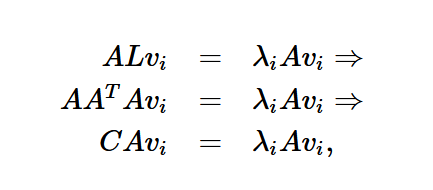

*ui *= *Avi* and *λi* are respectively the *M* eigenvectors and eigenvalues of *C. *

The *ui *eigenvectors are called "eigenfaces", which are used for the facial recognition and detection.

%% Description
% When file is run, it will load random image and find an image closest to
% the loaded image

%% Load random image and save it to variable for loading comparison later

loadedImage = outputImage;
loadedImage1 = outputImage1;
randomIndex = round(100*rand(1,1));          
randomImage = loadedImage1(:,randomIndex);

%% Get variables for analysis

% Store all images minus chosen image into an array
%remainingImages = loadedImage(:,[1:randomIndex - 1 randomIndex + 1:end]);
remainingImages = loadedImage(:,:);

% Blank image for resetting tracking images
blankImage = uint8(ones(1,size(remainingImages,2)));

% Find mean of remaining images and remove them from chosen image
meanValue = uint8(mean(remainingImages,2));                
meanRemovedImage = remainingImages - uint8(single(meanValue)*single(blankImage));

% Finding the eigenvector of image
A = single(meanRemovedImage)'*single(meanRemovedImage);
[V,D] = eig(A);
V = single(meanRemovedImage)*V;

% Create structures for each individual image
imageSignature = 20; % Play around with this   
V=V(:,end:-1:end-(imageSignature-1));          
allImageSignatures=zeros(size(remainingImages,2),imageSignature);

% Multiply eigenvectors and store with the image signatures
for i=1:size(remainingImages,2)
    allImageSignatures(i,:) = single(meanRemovedImage(:,i))'*V;  
end

## **4. Detailed Findings**

*This section should contain your main results and consequences of your work which you have quantied.This section should contain some clear, informative, labeled, and captioned plots and images that demonstrate your findings. Quantitative results should be clearly connected to the context of the investigation. Why are your findings meaningful? Reflect on the downsides of the technology and the people it could hurt, and suggest some strategies for improvement*

In order to test our algorithm, we have to run eigenvectors on all the images and compare them with the randomly chosen image. So first, the randomly selected image from the masked dataset was chosen for comparison against the non-masked dataset of images. After we check all the non-masked images for similarities, the algorithm chooses one image to select based on the previous algorithm explained in the Methods section and then displayed it next to the randomly selected masked image (as shown below)

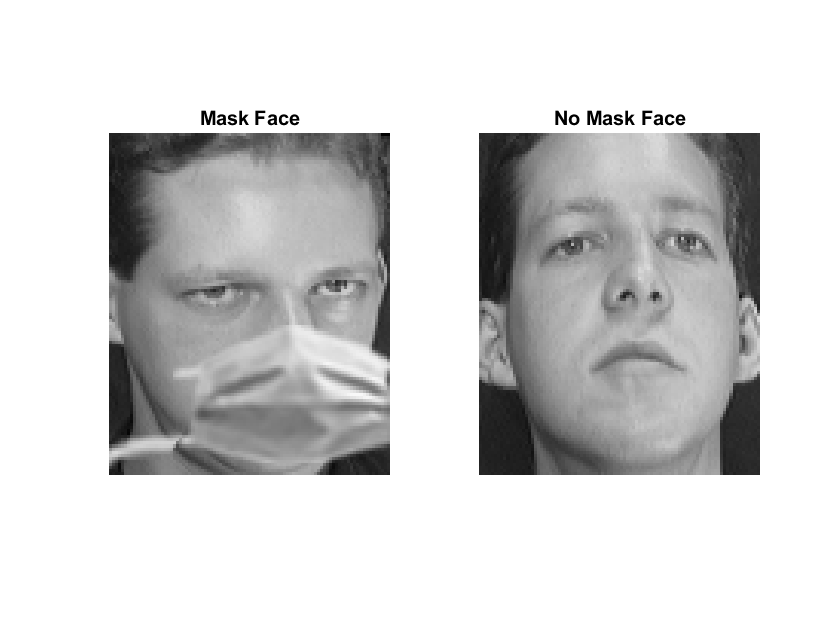

%% Find closest possible face

% Show random image onto a popup plot
subplot(121);
imshow(reshape(randomImage,112,92));
title('Mask Face');

% Calculate closest possible face
subplot(122);
p = randomImage-meanValue;
s = single(p)'*V;
B=[]; % empty array that stores search image signature

for i=1:size(remainingImages,2)
    B = [B,norm(allImageSignatures(i,:)-s,2)];
    if(rem(i,20) == 0),imshow(reshape(remainingImages(:,i),112,92)),end;
    drawnow;
end

% Show calculated closest image
[a,i] = min(B);
plot(122);
imshow(reshape(remainingImages(:,i),112,92));
title('No Mask Face');

## **5. Recommendations**

In summary, trying to use eigenvectors to match two images together where one image has a mask, and the other does not have a mask was relatively accurate. After utilizing the Eigenfaces algorithm to recognize masked faces and compare them with unmasked faces, there is proof of concept that facial recognition algorithms can help identify people even with a mask on their face. Although the system did occasionally get images incorrect, if we were to improve our system, we would most likely only rely on the upper half of the face (eyes and hair) to match images instead of using the masks as well since the masks were all identical in addition to fleshing out the training set even more. Moreover, although that would still cause inaccuracies in our model, it would also increase the accuracy of matching faces with their masked correspondents. Nevertheless, we can conclude that using eigenvectors to recognize face mask images is still a viable approach to identifying masked faces from unmasked faces and in the grand scheme of things. With a more extensive training set in diversity in our hands, image recognition techniques can be used to help identify people even with the mask covering a large portion of their faces.

## **6. References**

[1] Face Recognition Using Eigenfaces 1991 [Report](http://www.mit.edu/~9.54/fall14/Classes/class10/Turk%20Pentland%20Eigenfaces.pdf)

[2] ORL Training [Dataset](https://www.kaggle.com/kasikrit/att-database-of-faces) 40 Images

[3] [Context](http://cam-orl.co.uk/facedatabase.html) of the ORL Training Dataset

[4] [Eigenfaces](http://www.scholarpedia.org/article/Eigenfaces). Sheng Zhang and Matthew Turk (2008), Scholarpedia, 3(9):4244.

[5] Faces and Diagrams are courtesy of [Manfred Zabarauska ](http://blog.manfredas.com/eigenfaces-tutorial/)

## **7. Appendix**

All code for this project is available [here](https://github.com/DanPark13/Faces_Project)